## Blatt 6

clear;clc;

## Aufgabe 1


$$$\frac{\mathrm{d} \phi(t)}{\mathrm{d} t}=t^2 e^{-5 t}-6 \phi(t)$$$
 


$$$\phi(t)=e^{-5 t}\left(t^2-2 t+2\right)-2 e^{-6 t}$$$


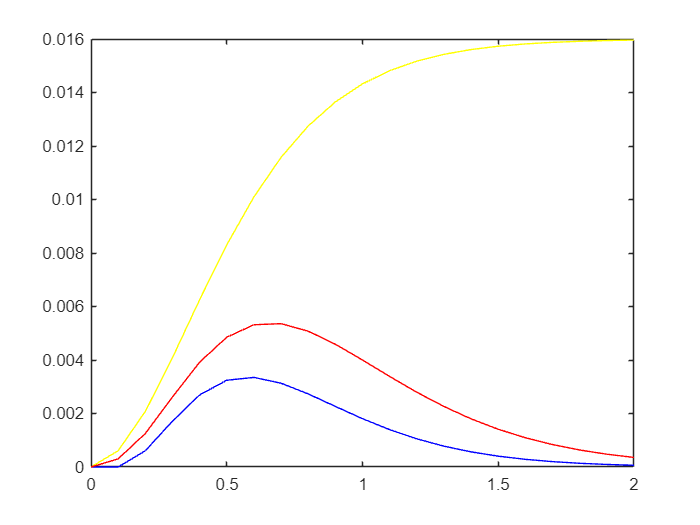

 % exakte Lösung
% fplot(@(t) exp(-5.*t).*(t.^2-2.*t+2)-2.*exp(-6.*t).0:0.01:2);
% Parameter setting
%theta,
timestep=[0.1];
theta=[0,1,1/2];
% Vorwärts-Euler Verfahren
for i=1:length(timestep)
    dt=timestep(i); % 步长
    t0=0:dt:2; % 由步长划分的时间
    len=length(t0); % 数组的长度
    phi=zeros(len,3);% 预分配数组长度。返回21*3的数组,
    % 分别存储forward,backward,trapetz不加zeros(len)是21*21
    for j=1:length(theta)
        % j=1 forward % j=2 backward 1% j=3 trapetz
        theta_=theta(j);
        for t=1:len-1 % 数组长度21，如果遍历1:len的话，会出现phi(22)的情况即越界% i本身是index
            % djd=phi(:,j)
            phi(t+1,j)=phi(t,j)+(theta_.*dt.*(f(t+1,phi(:,j),t0)))+((1-theta_).*dt.*f(t,phi(:,j),t0));
        end
    end
    
end
figure
plot(t0,phi(:,1),'b',t0,phi(:,2),'y',t0,phi(:,3),'r');



%0.000606530659712634


## Aufgabe 2

## Funktion

### Funktion phi(t)

function phi=f(i,phi,t0)
phi=(t0(i)^2)*exp(-5*t0(i))-6*phi(i);
end

allgemein Form:


$$$\phi_{n+1}=\phi_n+\theta \Delta t f\left(t_{n+1}, \phi_{n+1}\right)+(1-\theta) \Delta t f\left(t_n, \phi_n\right)$$$


function next_phi=cal_phi(phi,theta,timestep)
end

Funktion 9